nt = 2010;
dt = 0.5; % s
t = (0:nt-1)*dt;
fsignal = 0.02;
x = cos(2*pi*fsignal*t); % Dummy signal of length and freq similar to kidney TGF data

[wt, f, coi] = cwt(x, 'morse', 1/dt, 'FrequencyLimits', [0.007, 0.1], 'TimeBandwidth', 10);

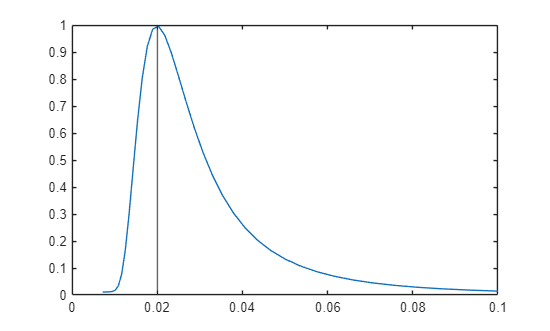

figure()
plot(f, mean(abs(wt), 2))
xline(fsignal)

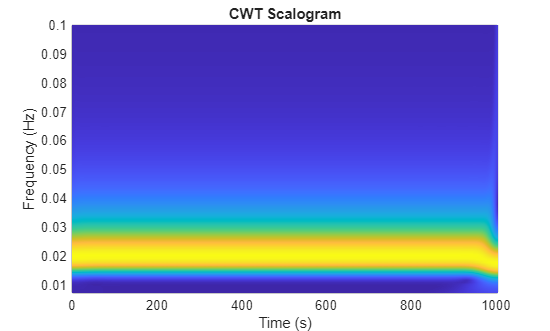

figure()
pcolor(t,f,abs(wt));
shading interp;
xlabel('Time (s)')
ylabel('Frequency (Hz)')
title('CWT Scalogram')